# Report 7 Mikołaj Suchoń

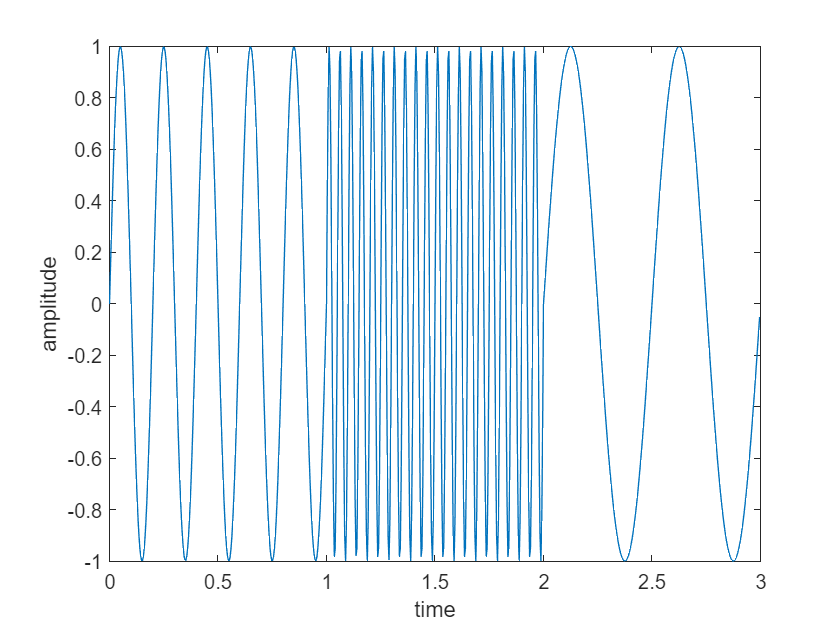

fs=250;
dt=1/fs;
t=0:dt:750*dt-dt;
x=sin(2*pi*5.*t(1:fs));
x(251:500)=sin(2*pi*20.*t(fs+1:fs*2));
x(501:750)=sin(2*pi*2.*t(2*fs+1:fs*3));
plot(t,x)
xlabel('time')
ylabel('amplitude')

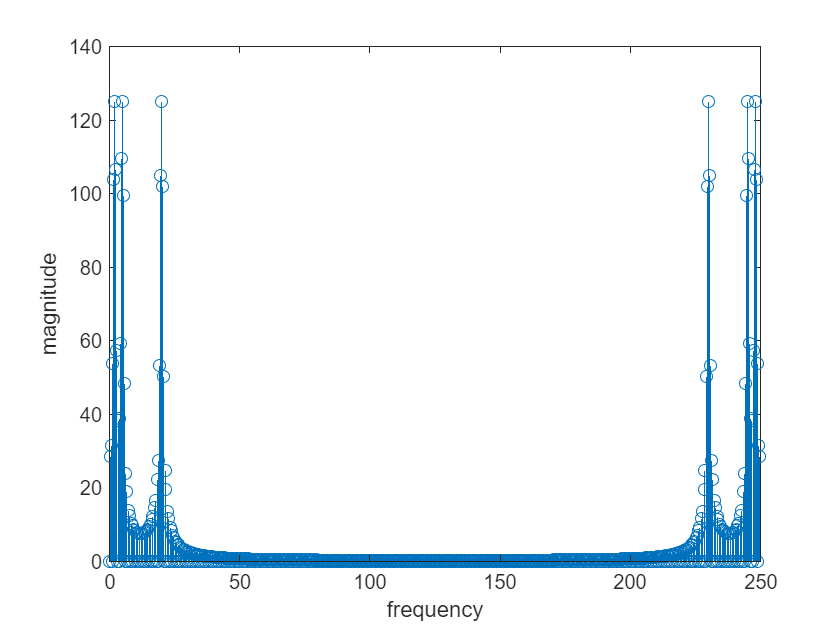

X=fft(x);
mag=abs(X);
n=length(t);
df=fs/n;
f=df*(0:n-1);
stem(f,mag)
xlabel('frequency')
ylabel('magnitude')

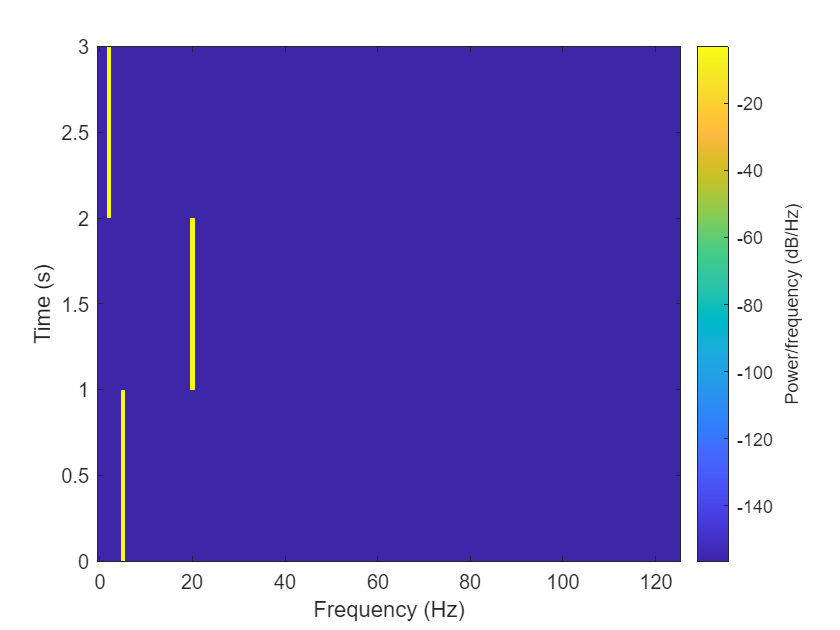


spectrogram(x,rectwin(250),0,250,fs);

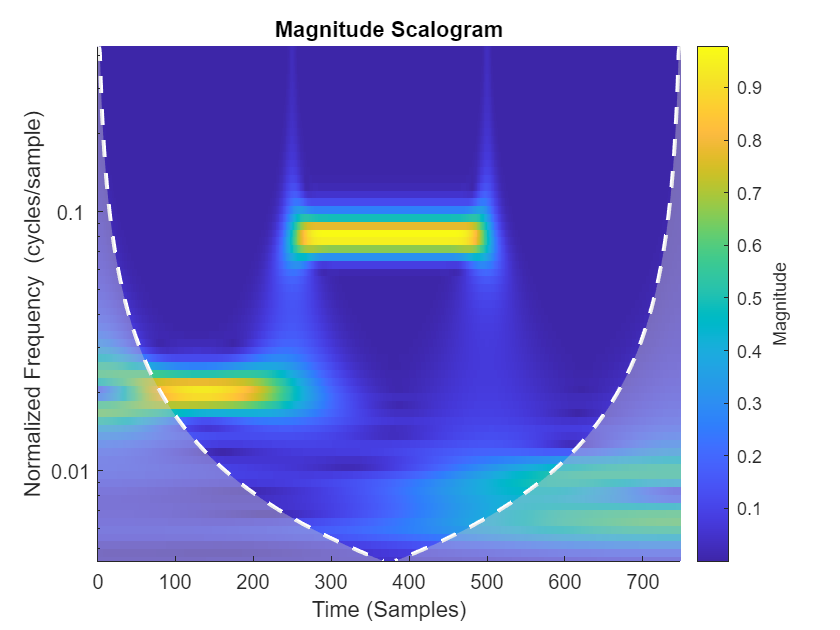

cwt(x);

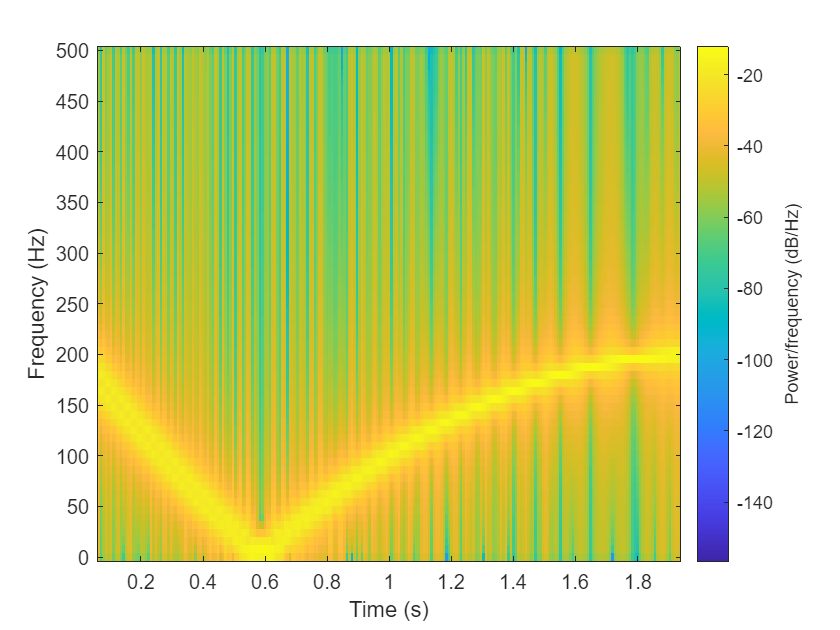

fs=1000;
dt=1/fs;
t=0:dt:2;
f0=100;
f1=200;
windowLength=128; noverlap=120; nfft=128;
x = chirp(t,f0,1,f1,'quadratic',[],'convex');
spectrogram(x,rectwin(windowLength),noverlap,nfft,fs,'yaxis');

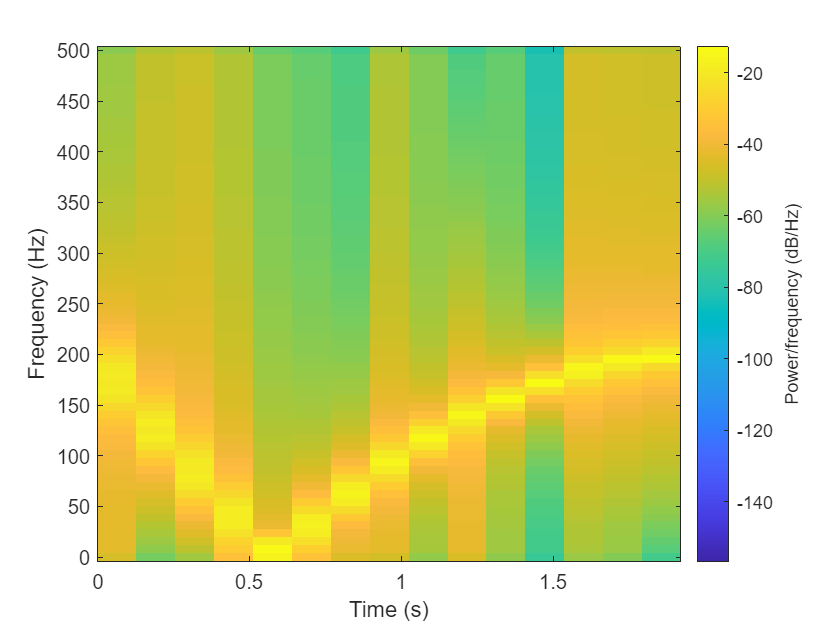


spectrogram(x,rectwin(windowLength),0,nfft,fs,'yaxis');

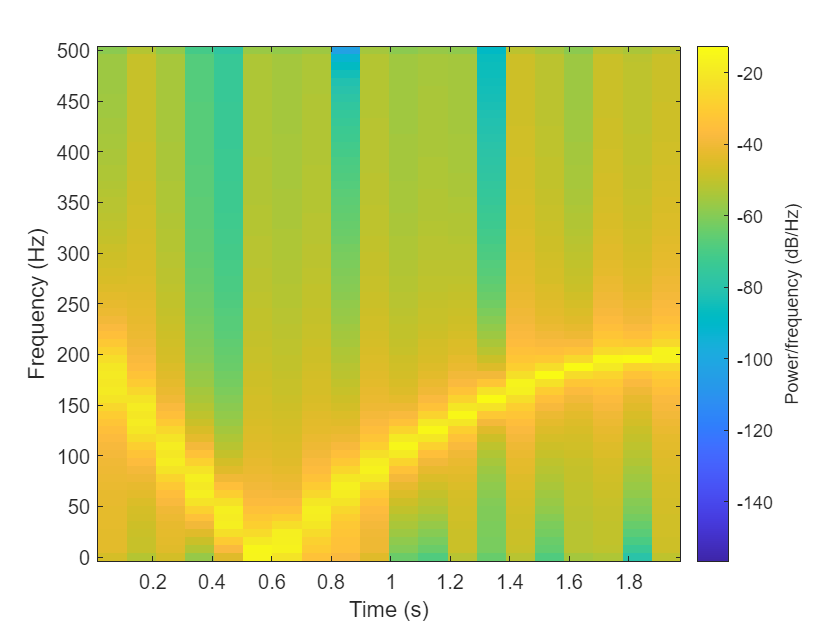

spectrogram(x,rectwin(windowLength),30,nfft,fs,'yaxis');

spectrogram(x,rectwin(windowLength),120,nfft,fs,'yaxis');

Overlapping helps to smooth the spectogram in the time axis while not affecting frequency axis

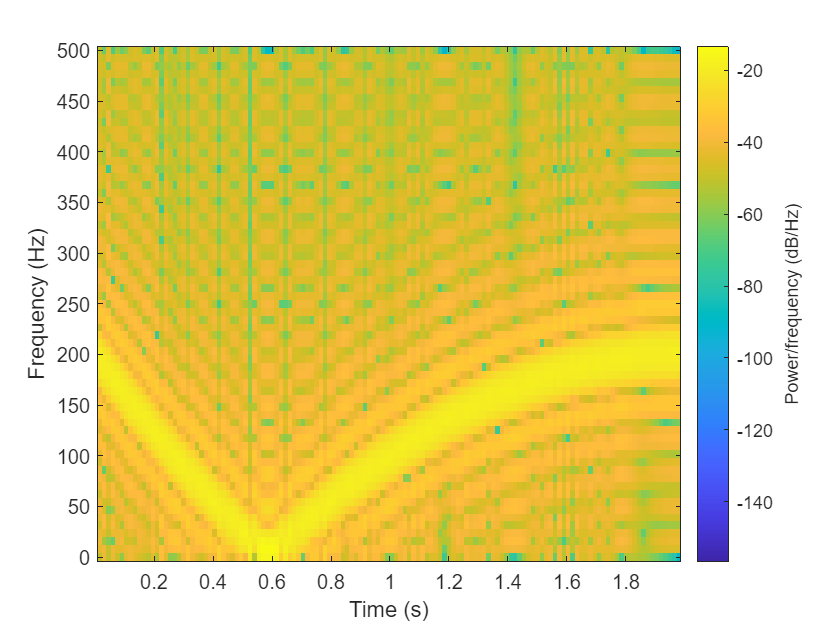


spectrogram(x,rectwin(30),15,nfft,fs,'yaxis');

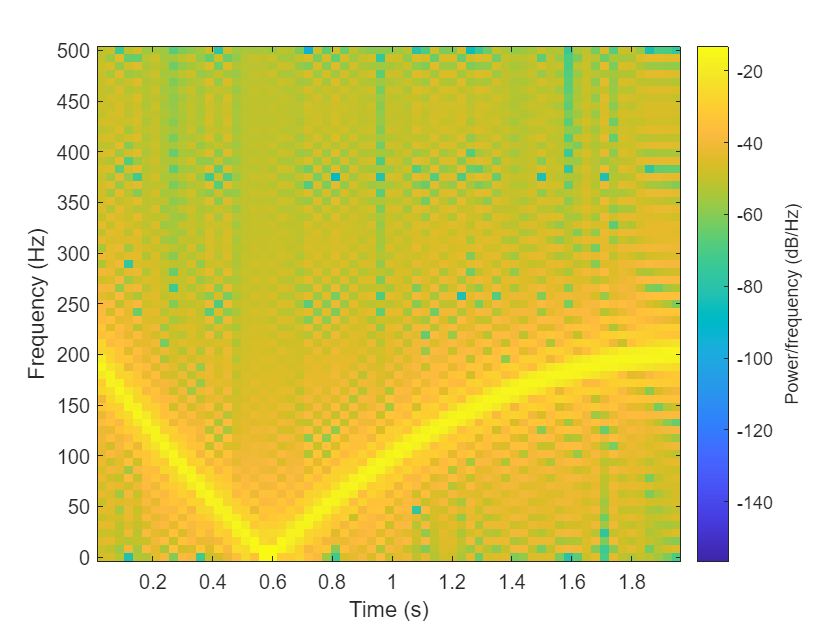

spectrogram(x,rectwin(60),30,nfft,fs,'yaxis');

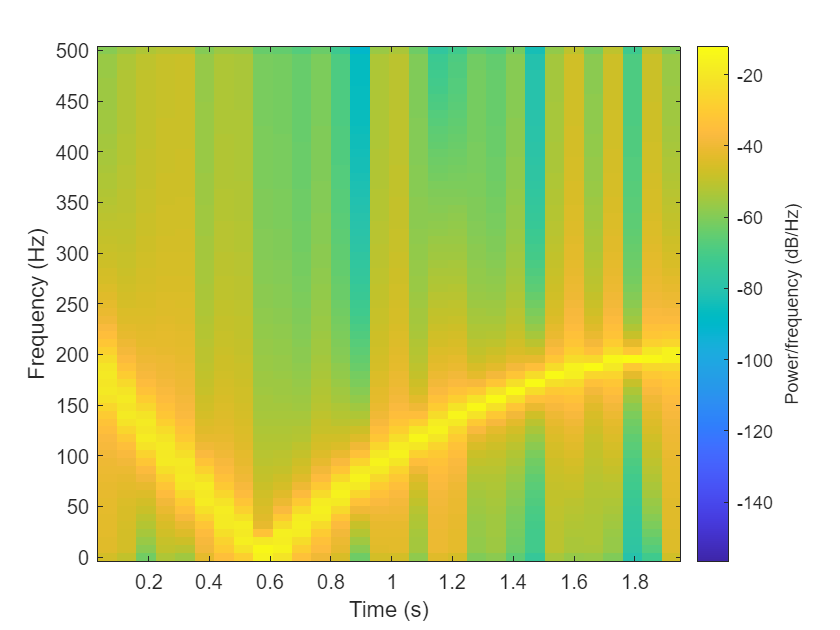

spectrogram(x,rectwin(128),64,nfft,fs,'yaxis');

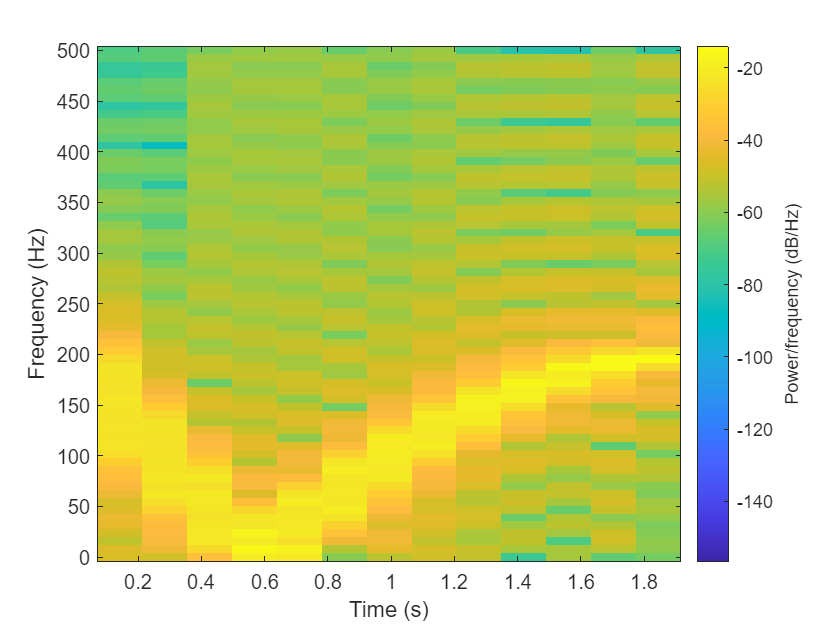

spectrogram(x,rectwin(284),142,nfft,fs,'yaxis');

Increacing window length provides us with better frequency resolution and a worst time resolution

This is besause (for a set sampling frequency) increacing the sampled time gives us better spectral resolution

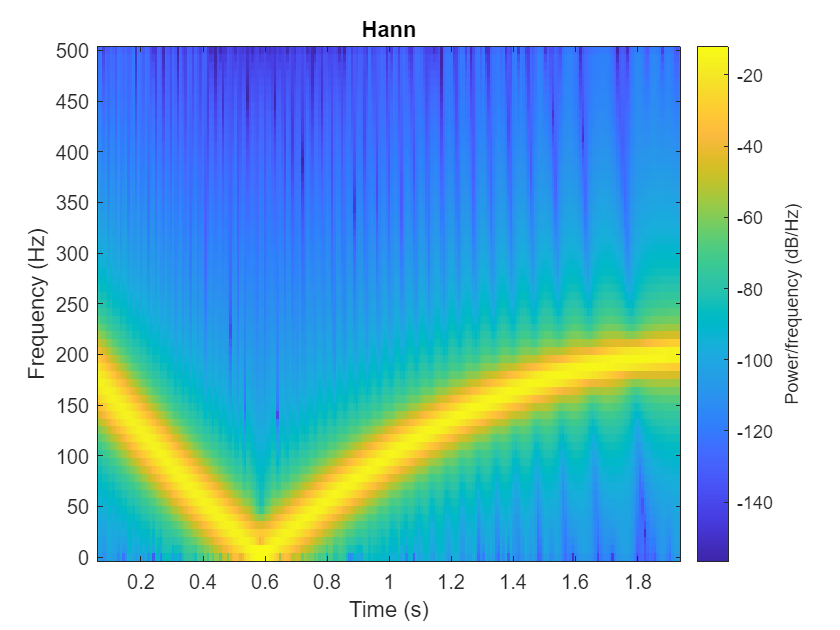

spectrogram(x,hann(windowLength),noverlap,nfft,fs,'yaxis');
title('Hann')

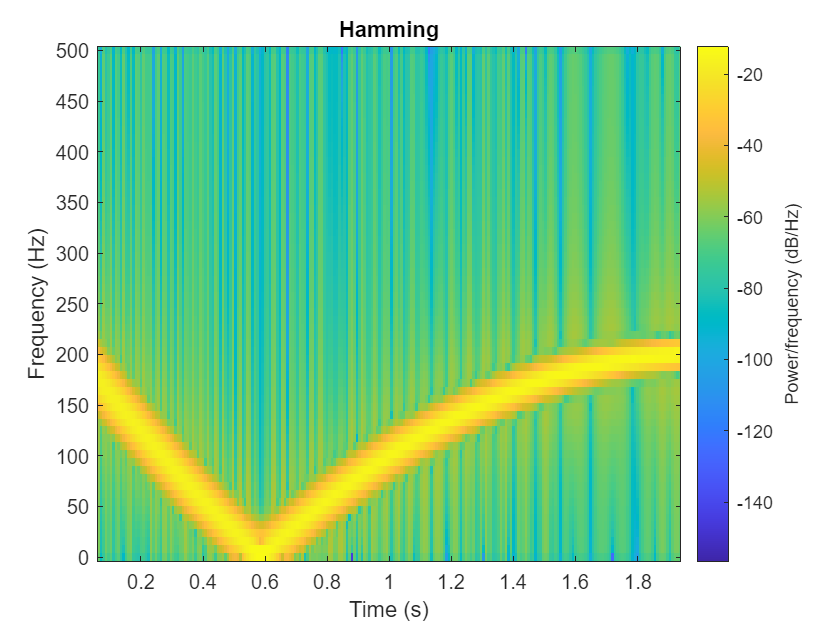

spectrogram(x,hamming(windowLength),noverlap,nfft,fs,'yaxis');
title('Hamming')

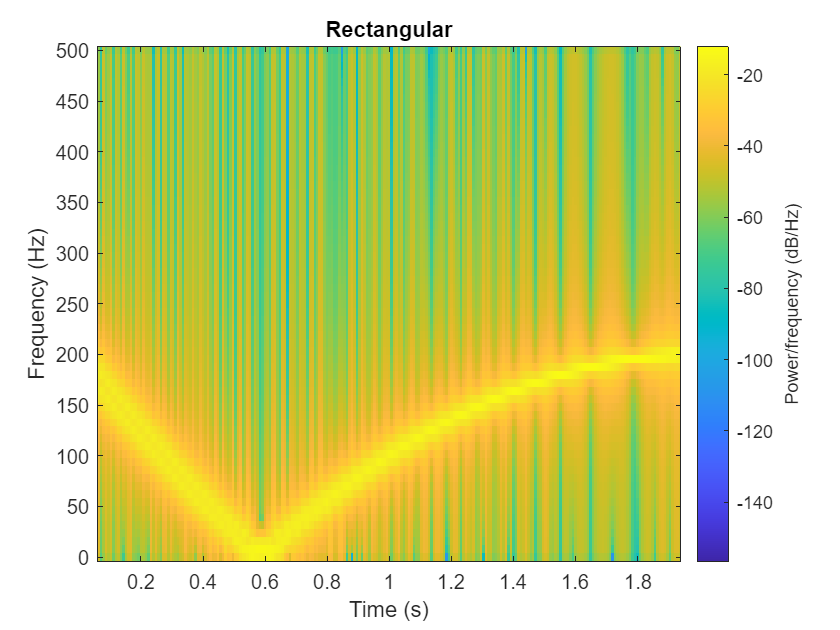

spectrogram(x,rectwin(windowLength),noverlap,nfft,fs,'yaxis');
title('Rectangular')

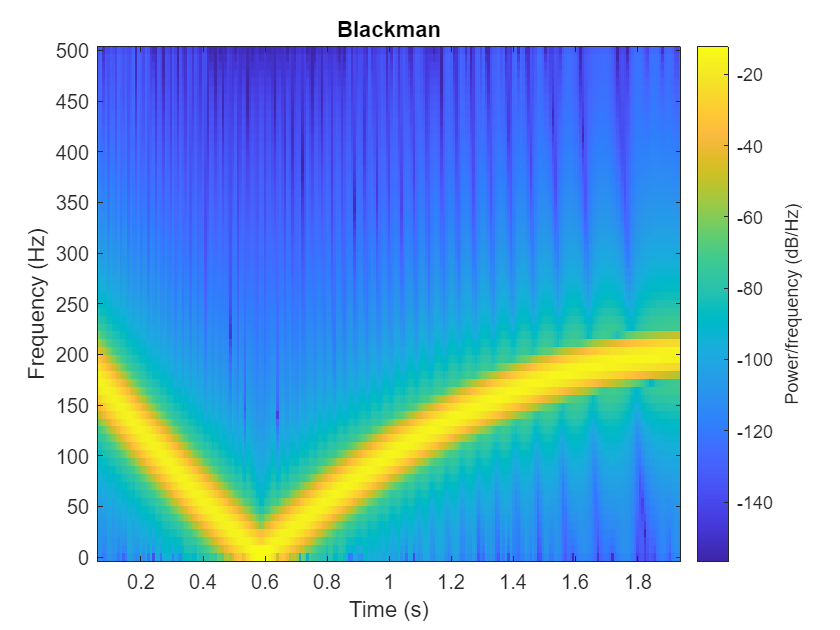

spectrogram(x,blackman(windowLength),noverlap,nfft,fs,'yaxis');
title('Blackman')

We observe the effects use of different window functions 

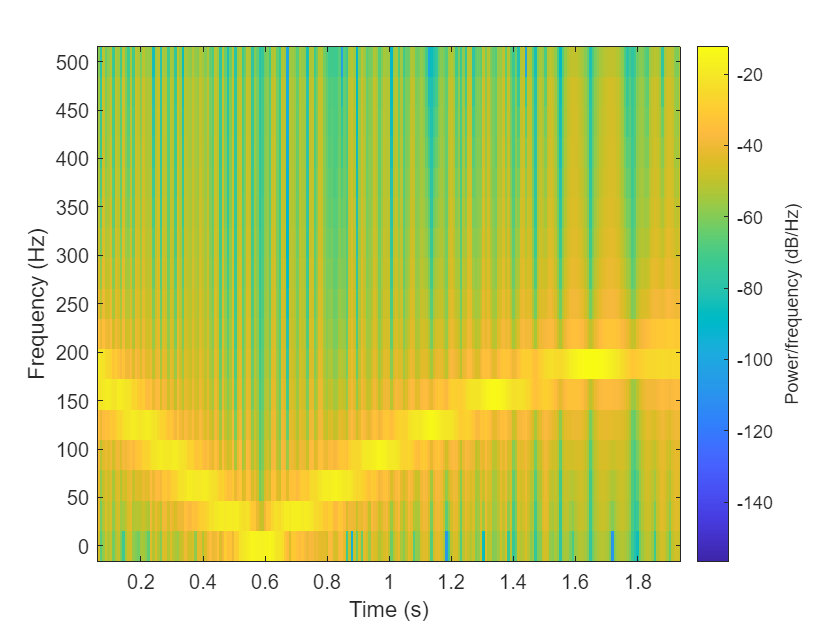


spectrogram(x,rectwin(windowLength),noverlap,2^5,fs,'yaxis');

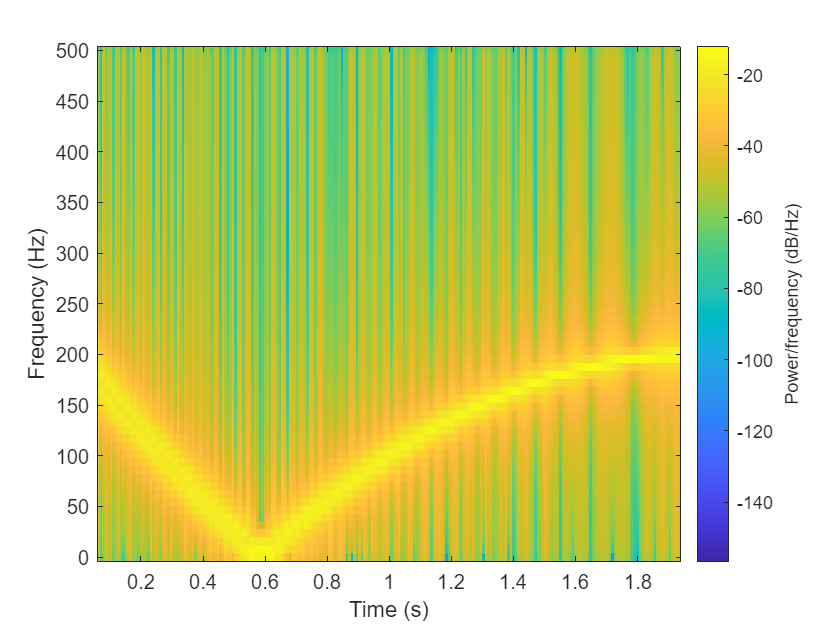

spectrogram(x,rectwin(windowLength),noverlap,2^7,fs,'yaxis');

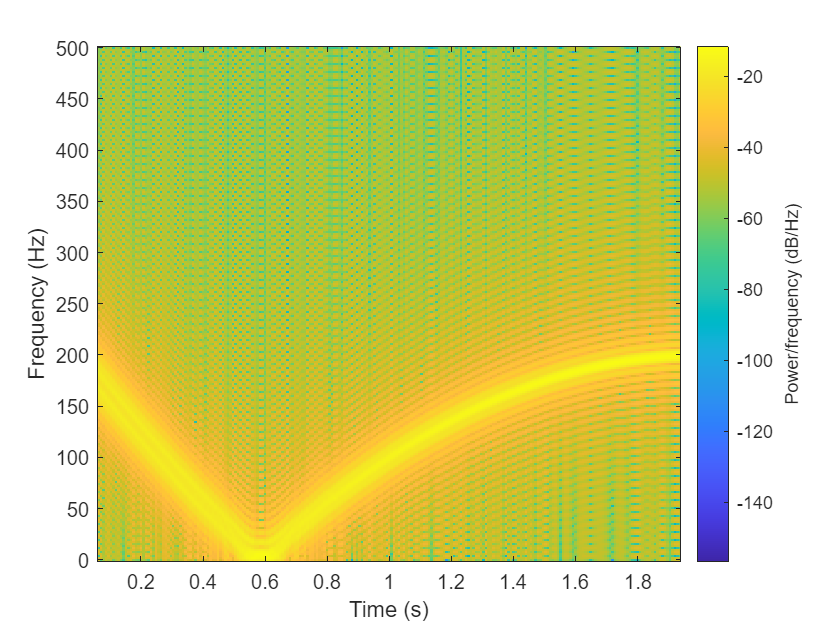

spectrogram(x,rectwin(windowLength),noverlap,2^9,fs,'yaxis');

Zero-padding sharpens the spectogram in the frequency axis while not affecting the time axis

clear
m1=10;
m2=5;
c1=8/4;
c2=1;
c3=10/3;
k1=8*1e4;
k2=k1;
k3=k1;
M2=[m1 0;0 m2];
C3=[c1+c2 -c3;-c2 c2+c3];
K2=[k1+k2 -k2;-k2 k2+k3];

%transmittance
s = tf('s');
T = 1/(M2.*s^2+C3.*s+K2)

T =
 
  From input 1 to output...
                   0.1 s^2 + 0.08667 s + 3200
   1:  ---------------------------------------------------
       s^4 + 1.167 s^3 + 4.8e04 s^2 + 1.653e04 s + 3.84e08
 
                          0.02 s + 1600
   2:  ---------------------------------------------------
       s^4 + 1.167 s^3 + 4.8e04 s^2 + 1.653e04 s + 3.84e08
 
  From input 2 to output...
                        0.06667 s + 1600
   1:  ---------------------------------------------------
       s^4 + 1.167 s^3 + 4.8e04 s^2 + 1.653e04 s + 3.84e08
 
                     0.2 s^2 + 0.06 s + 3200
   2:  ---------------------------------------------------
       s^4 + 1.167 s^3 + 4.8e04 s^2 + 1.653e04 s + 3.84e08
 
Continuous-time transfer function.



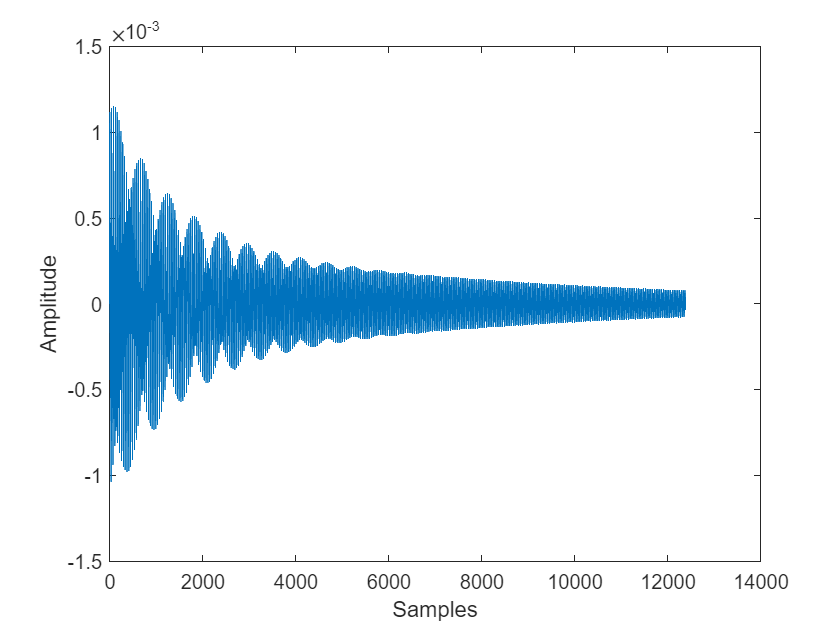

x=impulse(T(2,2),20)';
plot(x)
xlabel('Samples')
ylabel('Amplitude')

N=length(x);

[omega,~]=damp(T(2,2));
disp('natural frequency in Hz>>');disp(omega/(2*pi))

natural frequency in Hz>>
   16.0293
   16.0293
   30.9663
   30.9663



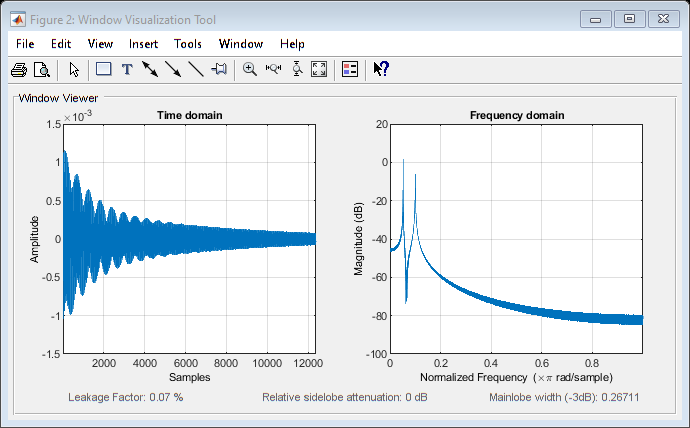



X=fft(x);
wvtool(x);

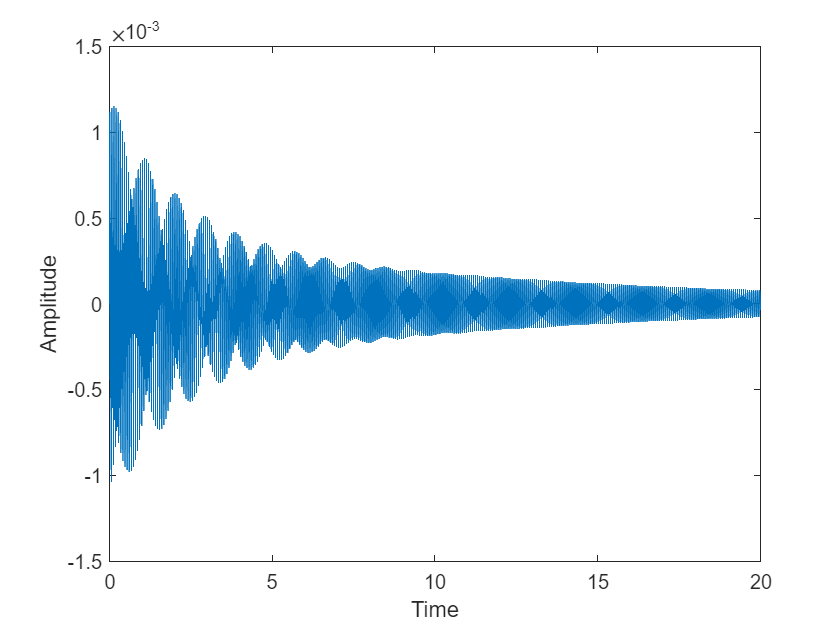

fs=619.4;
dt=1/fs;
t=0:dt:20-dt;
plot(t,x);
xlabel('Time')
ylabel('Amplitude')

df=N/fs;
f=df*(0:N-1);
mag=abs(X);
plot(f,mag)
xlabel('Frequency')
ylabel('Magnitude')

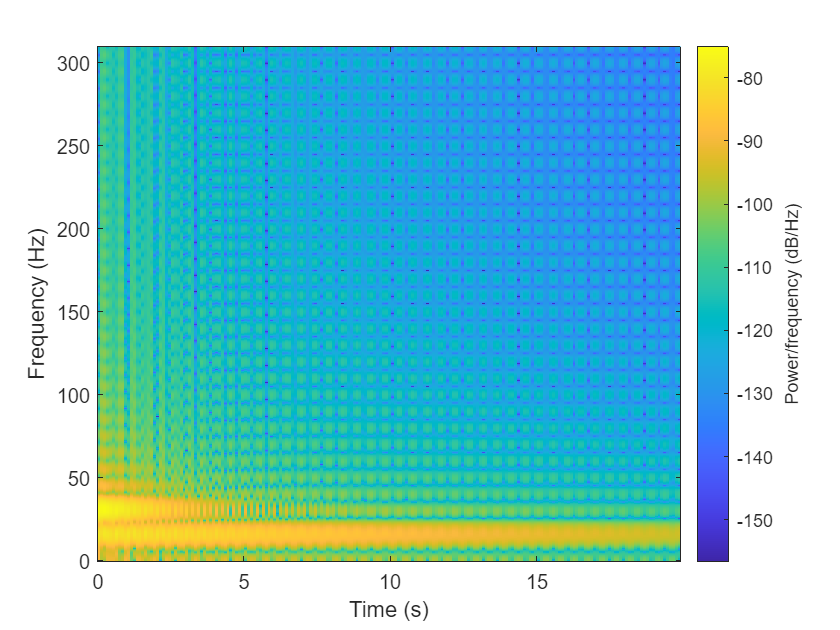

spectrogram(x,rectwin(124/2),0,32768, fs,'yaxis');

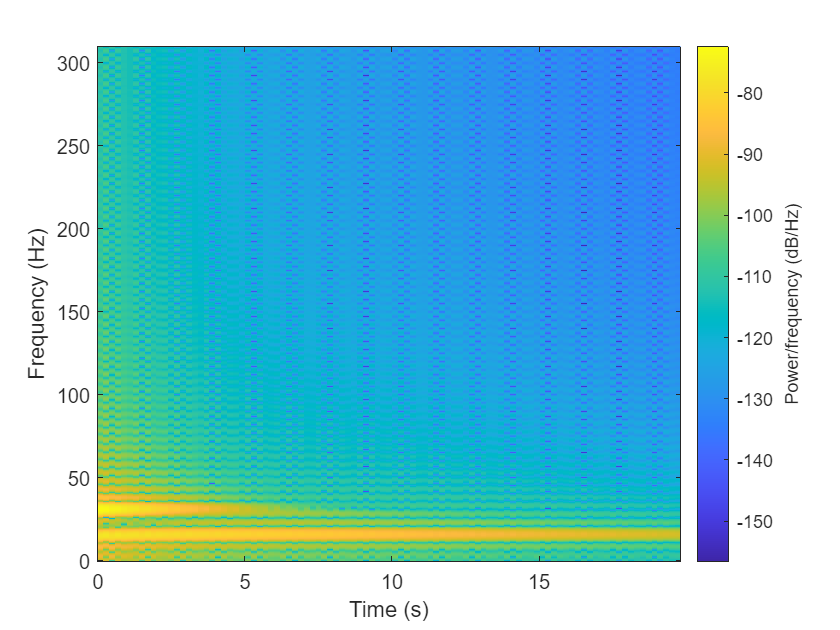

spectrogram(x,rectwin(124),0,32768, fs,'yaxis');

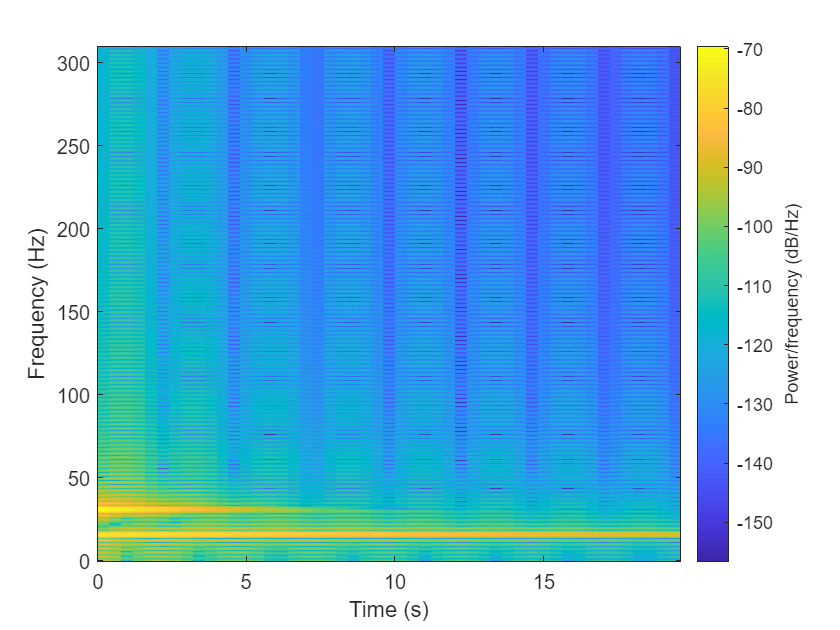

spectrogram(x,rectwin(124*2),0,32768, fs,'yaxis');